clear all; close all

Einlesen: hierfür lediglich die csv in eine xlsx und in Spalten teilen 

%format     
data2 = readtable("Naming.xlsx");

data = readtable("240423_good_75.xlsx");
%data1 = readtable("Naming.xlsx");

data.Properties.VariableNames = data2.Properties.VariableNames;

## Calculations

### Default Values

Colorcode: 

Blue 1:

Color.Blue1 = [0.109 0.424 0.784] ;

Blue 2: 

Color.Blue2 = [0.04 0.1 0.52];

 Red 1: 

Color.Red1 = [0.933 0.18 0.184];

Red 2

Color.Red2 = [0.635 0.114 0.129];

Green 1:

Color.Green1 = [0 0.549 0.282];

Pink 1:

Color.Pink1 = [0.851 0.263 0.706];

Black 1: 

Color.Black1 = [0 0 0];

Orange 1:

Color.Orange1 = [0.957 0.49 0.137];

Yellow 1:

Color.Yellow1 = [0.9290 0.6940 0.1250];

### Parameter einführen:

const.Delta_Qdot_norm    = 1; %_[kw]
const.Delta_T_norm        = 3; %_[K]
const.T_prim_hot_des	    = 53.5;%_[°C]
const.T_sec_hot_des	    = 50;%_[°C]
const.Delta_T_prim_des    = 20;%_[K]	
const.Delta_T_sec_des	    = 27;%_[K]
const.V_dot_sec_max	= 8.5;%_[l/min]
alpha.primprod = 0.66; 
alpha.primcons = 0.66; 
alpha.secprod = 0.33; 
alpha.seccons = 0.33; 

### Einführung Konstanten:

const.cv = 4190; % J/kg*K
const.mass = 1; % liter = kg
const.JoulemintokW = 1/60000; %1kW = 60'000 Joule/min

### Zählvariablen: 

i = 0; 
j = 1; 

Consume, Produce

ConsumeSF1 (size(data,1))= 0;
ConsumeSF1 = ConsumeSF1';
ProduceSF1 (size(data,1))= 0;
ProduceSF1 = ProduceSF1';

### Achsenbeschriftungen 

xAxis.Timemin = 'Time [min]';
xAxis.Timesec = 'Time [s]';
xAxis.Setpoint = 'Setpoints';
yAxis.Temp = 'Temperature [$^\circ$ C]';
yAxis.dTemp = 'Temperature deviation [K]';
yAxis.Q = 'Power [kW]';
yAxis.Flow = 'Volumeflow [l/min] ';
yAxis.In = 'Actuator input signal [V]';
yAxis.Qset = 'Setpoint for Q [kW]';
yAxis.Error = 'Weighted error';
yAxis.Pres = 'Pressure [bar]';

Default Werte 

set(0,'defaultTextInterpreter','latex');
set(0, 'DefaultLineLineWidth', 1.2);

Erstellen eines Arrays:

value = struct();
for col = 1:size(data, 2)
    array_name = data.Properties.VariableNames{col};
    value.(array_name) = table2array(data(:, col));
end

### Datenkürzung

Daten vor dem "Start" des Experiments löschen: 

ExpStart = 0; 
for i = 2 : size(value.Time_s_ ,1)
    if (value.SF1_fromLogic_CHN_CHN_P(i) ~= 0 && value.SF1_fromLogic_CHN_CHN_P(i-1) == 0)
    ExpStart = i; 
    end 
end 
data(1:ExpStart,:) = [];

Einschwingphase identifizieren : 

Change0(1)=0;
j = 1;
for i = 2 : size(value.Time_s_,1)
    if value.SF1_fromLogic_CHN_CHN_P(i)~=value.SF1_fromLogic_CHN_CHN_P(i-1)
        Change0(j) = i;
        j = j + 1; 
    end 
end 

t_einschwing = Change0(3) - (Change0(4) - Change0(3));

Werte nach Experiment löschen:

data((Change0(j-1) + (Change0(6) - Change0(5))):size(data,1),:) = [];

Werte vor Experiment löschen: 

data(1:t_einschwing,:) = [];

Error Spalten löschen: 

Errorcolum(size(data.Properties.VariableNames,2))=0; 
Tofind = 'Error'; 

for i = 1:size(data.Properties.VariableNames,2)
    if isempty(cell2mat(strfind(data.Properties.VariableNames(i),Tofind))) 
        Errorcolum(i) = 0;
    else 
        Errorcolum(i) = 1; 
        
    end 
end 


n = 1; 
for i = 1 : size(Errorcolum,2)
    if Errorcolum(i) == 1 
        Errorcolumn (n) = i; 
        n = n+1; 
    end     
end 
% data (:,Errorcolumn) = [];

Zeit von 0 starten lassen: 

data.Time_s_ = round(data.Time_s_ - data.Time_s_(1));

alte arrays löschen: 

clear value 

Erstellen eines neuen Arrays:

value = struct();
for col = 1:size(data, 2)
    array_name = data.Properties.VariableNames{col};
    value.(array_name) = table2array(data(:, col));
end
value.Time_min_ = value.Time_s_/60;

### Umschaltmomente identifizieren + Consume, Produce bestimmen 

Change1(1)=0;
j = 1;
for i = 2 : size(value.Time_s_,1)
    if value.SF1_fromLogic_CHN_CHN_P(i)~=value.SF1_fromLogic_CHN_CHN_P(i-1)
        Change1(j) = i;
         j = j + 1;
    end
    Inputs.SF1diffTemp (i) = 20;
    Inputs.SF2diffTemp (i) = 20;
    % SF1 Consume
    if value.SF1_fromLogic_CHN_A_PU_HC_TH_EXP(i) == 0
        ProduceSF1 (i) = 0;
        ConsumeSF1 (i) = 1;
        Inputs.SF1Temp (i) = 50;
        Inputs.SF2Temp (i) = 53.5;
        Inputs.SF1Mixer (i) = 30;
        Inputs.SF2Mixer (i) = 55; 

     %SF1 Produce
    elseif value.SF1_fromLogic_CHN_A_PU_HC_TH_EXP(i) ~= 0
        ProduceSF1 (i) = 1;
        ConsumeSF1 (i) = 0;
        Inputs.SF2Temp (i) = 50;
        Inputs.SF1Temp (i) = 53.5;
        Inputs.SF2Mixer (i) = 30;
        Inputs.SF1Mixer (i) = 55; 

    end 

end
Change = [Change1, size(data,1)];
Change0 = [0, Change1];
Changemin = Change0/60;
Change0end = [Change0, size(data,1)];
j = 1; 

### Inputs

for i = 1:size(Change,2)
Inputs.SF1P(i)=value.SF1_fromLogic_CHN_CHN_P(Change(i)-2);
Inputs.SF2P(i)=value.SF2_fromLogic_CHN_CHN_P(Change(i)-1);
Inputs.TM_TG_TH_set(i) = 53.5; 
Inputs.TM_HC_TH_set(i) = 50  ; 
xAxis.LabelSF11(i) = Inputs.SF1P(i);
xAxis.LabelSF21(i) = Inputs.SF2P(i);

end 

for i = 1:size(data,1)
value.SF1_fromLogic_CHN_S_TM_HC_TH_set(i) = 50; 
value.SF1_fromLogic_CHN_S_TM_HC_deltaT(i) = 20; 
value.SF1_fromLogic_CHN_S_TM_TG_TH_set(i) = 53.5; 
value.SF1_fromLogic_CHN_S_TM_TG_deltaT(i) = 20; 

value.SF2_fromLogic_CHN_S_TM_HC_TH_set(i) = 50; 
value.SF2_fromLogic_CHN_S_TM_HC_deltaT(i) = 20; 
value.SF2_fromLogic_CHN_S_TM_TG_TH_set(i) = 53.5; 
value.SF2_fromLogic_CHN_S_TM_TG_deltaT(i) = 20; 
end 

xAxis.LabelSF1 = num2cell(xAxis.LabelSF11);
% xAxis.LabelSF1(1) = {sprintf('Power SF1 in [kW]\n %d',Inputs.SF1P(1))};
xAxis.LabelSF2 = num2cell(xAxis.LabelSF21);
%xAxis.LabelSF2(1) = {sprintf('Power SF2 in [kW]\n %d',Inputs.SF2P(1))};
clear xAxis.LabelSF11
clear xAxis.LabelSF22

Fehler: 


$$K_{J\;}^{i\;\;} =\frac{\alpha_{j\;}^{i\;} }{\dot{\;Q{\;}_{\textrm{norm}\;} } }$$



$$G_{J\;}^{i\;\;} =\frac{1-\alpha_{j\;}^{i\;} }{\dot{\;\Delta \;T{\;}_{\textrm{norm}\;} } }$$


K.primprod = alpha.primprod / const.Delta_Qdot_norm; 
K.primcons = alpha.primcons / const.Delta_Qdot_norm; 
K.secprod = alpha.secprod / const.Delta_Qdot_norm; 
K.seccons = alpha.seccons / const.Delta_Qdot_norm; 

G.primprod = (1-alpha.primprod) / const.Delta_T_norm; 
G.primcons = (1-alpha.primcons) / const.Delta_T_norm; 
G.secprod = (1-alpha.secprod) / const.Delta_T_norm; 
G.seccons = (1-alpha.seccons) / const.Delta_T_norm; 


e.SF1primcons = K.primcons * (value.SF1_fromLogic_CHN_CHN_P - value.SF1_Calc_CHN_P_TH) + (-G.primcons)*(const.Delta_T_sec_des-(value.SF1_read_CHN_S_TM_TG_TH_1-value.SF1_read_CHN_S_TM_TG_TM_1));
e.SF1primprod = K.primprod * (value.SF1_fromLogic_CHN_CHN_P - value.SF1_Calc_CHN_P_TH) + (G.primprod)*(const.Delta_T_prim_des-(value.SF1_read_CHN_S_TM_HC_TH_1-value.SF1_read_CHN_S_TM_HC_TM_1));
e.SF1seccons = K.seccons * (value.SF1_fromLogic_CHN_CHN_P - value.SF1_Calc_CHN_P_TH) + (-G.seccons)*(const.T_sec_hot_des-value.SF1_read_CHN_S_TM_HC_TH_1); %sign of G changed by Thomas L
e.SF1secprod = K.secprod * (value.SF1_fromLogic_CHN_CHN_P - value.SF1_Calc_CHN_P_TH) + (G.secprod)*(const.T_prim_hot_des-value.SF1_read_CHN_S_TM_TG_TH_1);

e.SF2primcons = K.primcons * (value.SF2_fromLogic_CHN_CHN_P - value.SF2_Calc_CHN_P_TH) + (-G.primcons)*(const.Delta_T_sec_des-(value.SF2_read_CHN_S_TM_TG_TH_1-value.SF2_read_CHN_S_TM_TG_TM_1));
e.SF2primprod = K.primprod * (value.SF2_fromLogic_CHN_CHN_P - value.SF2_Calc_CHN_P_TH) + (G.primprod)*(const.Delta_T_prim_des-(value.SF2_read_CHN_S_TM_HC_TH_1-value.SF2_read_CHN_S_TM_HC_TM_1));
e.SF2seccons = K.seccons * (value.SF2_fromLogic_CHN_CHN_P - value.SF2_Calc_CHN_P_TH) + (-G.seccons)*(const.T_sec_hot_des-value.SF2_read_CHN_S_TM_HC_TH_1); %sign of G changed by Thomas L
e.SF2secprod = K.secprod * (value.SF2_fromLogic_CHN_CHN_P - value.SF2_Calc_CHN_P_TH) + (G.secprod)*(const.T_prim_hot_des-value.SF2_read_CHN_S_TM_TG_TH_1);

jetzt e in Prod und cons für Proucder und Consumer 

for i = 1:size(data,1)
    if ConsumeSF1(i) == 1
        e.SF1prim(i) =  e.SF1primcons(i);
        e.SF1sec(i) =  e.SF1seccons(i);
        e.SF2prim(i) =  e.SF1primprod(i);
        e.SF2sec(i) =  e.SF2secprod(i);
    elseif ProduceSF1(i)==1
        e.SF1prim(i) =  e.SF1primprod(i);
        e.SF1sec(i) =  e.SF1secprod(i);
        e.SF2prim(i) =  e.SF1primcons(i);
        e.SF2sec(i) =  e.SF2seccons(i);
    end 
end 

Fehlerbearbeitung: 

for i = 1:size(data,1)
    % Fehler: Differenz von Soll und Istwert 
    value.SF1_e_cons_prim_dT(i) =  value.SF1_e_cons_prim_dT_set(i)-value.SF1_e_cons_prim_dT_is(i);
    value.SF1_e_cons_prim_Q(i) =  value.SF1_e_cons_prim_Q_set(i)-value.SF1_e_cons_prim_Q_is(i);
    value.SF1_e_cons_sec_Q(i) =  value.SF1_e_cons_sec_Q_set(i)-value.SF1_e_cons_sec_Q_is(i);
    value.SF1_e_cons_sec_T(i) =  value.SF1_e_cons_sec_T_set(i)-value.SF1_e_cons_sec_T_is(i);
    %Fehler: Fehler jedes Aktores; jeweils ist und soll 
    value.SF1_e_cons_prim_is(i) = value.SF1_e_cons_prim_dT_is(i) + value.SF1_e_cons_prim_Q_is(i);
    value.SF1_e_cons_prim_set(i) = value.SF1_e_cons_prim_dT_set(i) + value.SF1_e_cons_prim_Q_set(i);
    value.SF1_e_cons_sec_set(i) = value.SF1_e_cons_sec_T_set(i) + value.SF1_e_cons_sec_Q_set(i);
    value.SF1_e_cons_sec_is(i) = value.SF1_e_cons_sec_T_is(i) + value.SF1_e_cons_sec_Q_is(i);
    % Fehler: Differenz von Soll und Istwert 
    value.SF1_e_pro_prim_dT(i) =  value.SF1_e_pro_prim_dT_set(i)-value.SF1_e_pro_prim_dT_is(i);
    value.SF1_e_pro_prim_Q(i) =  value.SF1_e_pro_prim_Q_set(i)-value.SF1_e_pro_prim_Q_is(i);
    value.SF1_e_pro_sec_Q(i) =  value.SF1_e_pro_sec_Q_set(i)-value.SF1_e_pro_sec_Q_is(i);
    value.SF1_e_pro_sec_T(i) =  value.SF1_e_pro_sec_T_set(i)-value.SF1_e_pro_sec_T_is(i);
    %Fehler: Fehler jedes Aktores; jeweils ist und soll 
    value.SF1_e_pro_prim_is(i) = value.SF1_e_pro_prim_dT_is(i) + value.SF1_e_pro_prim_Q_is(i);
    value.SF1_e_pro_prim_set(i) = value.SF1_e_pro_prim_dT_set(i) + value.SF1_e_pro_prim_Q_set(i);
    value.SF1_e_pro_sec_set(i) = value.SF1_e_pro_sec_T_set(i) + value.SF1_e_pro_sec_Q_set(i);
    value.SF1_e_pro_sec_is(i) = value.SF1_e_pro_sec_T_is(i) + value.SF1_e_pro_sec_Q_is(i);
    % Fehler: Differenz von Soll und Istwert 
    value.SF2_e_cons_prim_dT(i) =  value.SF2_e_cons_prim_dT_set(i)-value.SF2_e_cons_prim_dT_is(i);
    value.SF2_e_cons_prim_Q(i) =  value.SF2_e_cons_prim_Q_set(i)-value.SF2_e_cons_prim_Q_is(i);
    value.SF2_e_cons_sec_Q(i) =  value.SF2_e_cons_sec_Q_set(i)-value.SF2_e_cons_sec_Q_is(i);
    value.SF2_e_cons_sec_T(i) =  value.SF2_e_cons_sec_T_set(i)-value.SF2_e_cons_sec_T_is(i);
    %Fehler: Fehler jedes Aktores; jeweils ist und soll 
    value.SF2_e_cons_prim_is(i) = value.SF2_e_cons_prim_dT_is(i) + value.SF2_e_cons_prim_Q_is(i);
    value.SF2_e_cons_prim_set(i) = value.SF2_e_cons_prim_dT_set(i) + value.SF2_e_cons_prim_Q_set(i);
    value.SF2_e_cons_sec_set(i) = value.SF2_e_cons_sec_T_set(i) + value.SF2_e_cons_sec_Q_set(i);
    value.SF2_e_cons_sec_is(i) = value.SF2_e_cons_sec_T_is(i) + value.SF2_e_cons_sec_Q_is(i);
    % Fehler: Differenz von Soll und Istwert 
    value.SF2_e_pro_prim_dT(i) =  value.SF2_e_pro_prim_dT_set(i)-value.SF2_e_pro_prim_dT_is(i);
    value.SF2_e_pro_prim_Q(i) =  value.SF2_e_pro_prim_Q_set(i)-value.SF2_e_pro_prim_Q_is(i);
    value.SF2_e_pro_sec_Q(i) =  value.SF2_e_pro_sec_Q_set(i)-value.SF2_e_pro_sec_Q_is(i);
    value.SF2_e_pro_sec_T(i) =  value.SF2_e_pro_sec_T_set(i)-value.SF2_e_pro_sec_T_is(i);
    %Fehler: Fehler jedes Aktores; jeweils ist und soll 
    value.SF2_e_pro_prim_is(i) = value.SF2_e_pro_prim_dT_is(i) + value.SF2_e_pro_prim_Q_is(i);
    value.SF2_e_pro_prim_set(i) = value.SF2_e_pro_prim_dT_set(i) + value.SF2_e_pro_prim_Q_set(i);
    value.SF2_e_pro_sec_set(i) = value.SF2_e_pro_sec_T_set(i) + value.SF2_e_pro_sec_Q_set(i);
    value.SF2_e_pro_sec_is(i) = value.SF2_e_pro_sec_T_is(i) + value.SF2_e_pro_sec_Q_is(i);
end 

Relevante Fehler: 

for i = 1:size(data,1)

    if ConsumeSF1 (i) == 1
    value.SF1_e_prim_is(i) = value.SF1_e_cons_prim_is(i);
    value.SF1_e_prim_set(i) = value.SF1_e_cons_prim_set(i);
    value.SF1_e_sec_is(i) = value.SF1_e_cons_sec_is(i);
    value.SF1_e_sec_set(i) = value.SF1_e_cons_sec_set(i);
    
    value.SF2_e_prim_is(i) = value.SF2_e_pro_prim_is(i);
    value.SF2_e_prim_set(i) = value.SF2_e_pro_prim_set(i);
    value.SF2_e_sec_is(i) = value.SF2_e_pro_sec_is(i);
    value.SF2_e_sec_set(i) = value.SF2_e_pro_sec_set(i);
  
    elseif  ProduceSF1(i)==1
    value.SF1_e_prim_is(i) = value.SF1_e_pro_prim_is(i);
    value.SF1_e_prim_set(i) = value.SF1_e_pro_prim_set(i);
    value.SF1_e_sec_is(i) = value.SF1_e_pro_sec_is(i);
    value.SF1_e_sec_set(i) = value.SF1_e_pro_sec_set(i);

    value.SF2_e_prim_is(i) = value.SF2_e_cons_prim_is(i);
    value.SF2_e_prim_set(i) = value.SF2_e_cons_prim_set(i);
    value.SF2_e_sec_is(i) = value.SF2_e_cons_sec_is(i);
    value.SF2_e_sec_set(i) = value.SF2_e_cons_sec_set(i);
    end 
end 

Relevante Temperaturen 

for i = 1:size(data,1)

    if ConsumeSF1 (i) == 1
    value.SF2_dT(i) = value.SF2_read_CHN_S_TM_HC_TH_1(i) - value.SF2_read_CHN_S_TM_HC_TM_1(i);
    value.SF1_dT(i) = value.SF1_read_CHN_S_TM_TG_TH_1(i) - value.SF1_read_CHN_S_TM_TG_TM_1(i);
    value.SF2_T(i) = value.SF2_read_CHN_S_TM_TG_TH_1(i); 
    value.SF1_T(i) = value.SF1_read_CHN_S_TM_HC_TH_1(i); 
    
    elseif  ProduceSF1(i)==1
    value.SF1_dT(i) = value.SF1_read_CHN_S_TM_HC_TH_1(i) - value.SF1_read_CHN_S_TM_HC_TM_1(i);     
    value.SF2_dT(i) = value.SF2_read_CHN_S_TM_TG_TH_1(i) - value.SF2_read_CHN_S_TM_TG_TM_1(i); 
    value.SF1_T(i) = value.SF1_read_CHN_S_TM_TG_TH_1(i); 
    value.SF2_T(i) = value.SF2_read_CHN_S_TM_HC_TH_1(i); 
    end
end  

Boundaryconditions:

for i = 1:size(data,1)

    if ConsumeSF1 (i) == 1
    value.SF1_boundary_temp(i) = value.SF1_read_CHN_S_TM_HC_TM_1(i);
    value.SF2_boundary_temp(i) = value.SF2_read_CHN_S_TM_HC_TH_1(i);

    elseif  ProduceSF1(i)==1
    value.SF1_boundary_temp(i) = value.SF1_read_CHN_S_TM_HC_TH_1(i);
    value.SF2_boundary_temp(i) = value.SF2_read_CHN_S_TM_HC_TM_1(i);
    end 
end 

### Aktive Aktoren: 

for i = 1:size(data,1)

    if ConsumeSF1 (i) == 1
    value.SF1_prim_active(i) = value.SF1_fromLogic_CHN_A_CV_TG_TH(i);
    value.SF1_sec_active(i) = value.SF1_fromLogic_CHN_A_PU_HC_TH_IMP(i);

    value.SF2_prim_active(i) = value.SF2_fromLogic_CHN_A_PU_HC_TH_EXP(i); 
    value.SF2_sec_active(i) = value.SF2_fromLogic_CHN_A_PU_TG_TH(i);
    
    elseif  ProduceSF1(i)==1
    value.SF1_prim_active(i) = value.SF1_fromLogic_CHN_A_PU_HC_TH_EXP(i); 
    value.SF1_sec_active(i) = value.SF1_fromLogic_CHN_A_PU_TG_TH(i); 

    value.SF2_prim_active(i) = value.SF2_fromLogic_CHN_A_CV_TG_TH(i);
    value.SF2_sec_active(i) = value.SF2_fromLogic_CHN_A_PU_HC_TH_IMP(i);
    end
end     

### Errors from measurements - relevant errors

for i = 1:size(data,1)
    value.SF1_e_prim(i) = value.SF1_e_prim_set(i) -value.SF1_e_prim_is(i);
    value.SF1_e_sec(i) = value.SF1_e_sec_set(i) - value.SF1_e_sec_is(i);
    value.SF2_e_prim(i) = value.SF1_e_prim_set(i) - value.SF1_e_prim_is(i);
    value.SF2_e_sec(i) = value.SF1_e_sec_set(i) - value.SF1_e_sec_is(i);
end

### Calculate unweighted errors and average them to get MAE

unweighted Errors: 

for i = 1:size(data,1)
    value.SF1_e_cons_prim_unweighted_dT (i) = value.SF1_fromLogic_CHN_S_TM_TG_deltaT (i) - (value.SF1_read_CHN_S_TM_TG_TH_1(i) - value.SF1_read_CHN_S_TM_TG_TM_1(i)); %Delta T TG soll - Delta T TG ist; 
    value.SF1_e_pro_prim_unweighted_dT (i) = value.SF1_fromLogic_CHN_S_TM_HC_deltaT (i) - (value.SF1_read_CHN_S_TM_HC_TH_1(i) - value.SF1_read_CHN_S_TM_HC_TM_1(i)); %Delta T HC soll - Delta T HC ist; 
    value.SF1_e_cons_sec_unweighted_T (i) = value.SF1_fromLogic_CHN_S_TM_HC_TH_set (i) - value.SF1_read_CHN_S_TM_HC_TH_1 (i); 
    value.SF1_e_pro_sec_unweighted_T (i) = value.SF1_fromLogic_CHN_S_TM_TG_TH_set (i) - value.SF1_read_CHN_S_TM_TG_TH_1 (i); 

    value.SF1_e_cons_prim_unweighted_Q (i) = value.SF1_fromLogic_CHN_CHN_P (i) + value.SF1_Calc_CHN_P_TH (i); 
    value.SF1_e_pro_prim_unweighted_Q (i) = value.SF1_fromLogic_CHN_CHN_P (i) + value.SF1_Calc_CHN_P_TH (i); 
    value.SF1_e_cons_sec_unweighted_Q (i) = value.SF1_fromLogic_CHN_CHN_P (i) + value.SF1_Calc_CHN_P_TH (i); 
    value.SF1_e_pro_sec_unweighted_Q (i) = value.SF1_fromLogic_CHN_CHN_P (i) + value.SF1_Calc_CHN_P_TH (i); 

    value.SF2_e_cons_prim_unweighted_dT (i) = value.SF2_fromLogic_CHN_S_TM_TG_deltaT (i) - (value.SF2_read_CHN_S_TM_TG_TH_1(i) - value.SF2_read_CHN_S_TM_TG_TM_1(i)); %Delta T TG soll - Delta T TG ist; 
    value.SF2_e_pro_prim_unweighted_dT (i) = value.SF2_fromLogic_CHN_S_TM_HC_deltaT (i) - (value.SF2_read_CHN_S_TM_HC_TH_1(i) - value.SF2_read_CHN_S_TM_HC_TM_1(i)); %Delta T HC soll - Delta T HC ist; 
    value.SF2_e_cons_sec_unweighted_T (i) = value.SF2_fromLogic_CHN_S_TM_HC_TH_set (i) - value.SF2_read_CHN_S_TM_HC_TH_1 (i); 
    value.SF2_e_pro_sec_unweighted_T (i) = value.SF2_fromLogic_CHN_S_TM_TG_TH_set (i) - value.SF2_read_CHN_S_TM_TG_TH_1 (i); 

    value.SF2_e_cons_prim_unweighted_Q (i) = value.SF2_fromLogic_CHN_CHN_P (i) + value.SF2_Calc_CHN_P_TH (i); 
    value.SF2_e_pro_prim_unweighted_Q (i) = value.SF2_fromLogic_CHN_CHN_P (i) + value.SF2_Calc_CHN_P_TH (i); 
    value.SF2_e_cons_sec_unweighted_Q (i) = value.SF2_fromLogic_CHN_CHN_P (i) + value.SF2_Calc_CHN_P_TH (i); 
    value.SF2_e_pro_sec_unweighted_Q (i) = value.SF2_fromLogic_CHN_CHN_P (i) + value.SF2_Calc_CHN_P_TH (i); 
    
end

nur relevante Fehler: 

for i = 1:size(data,1)

    if ConsumeSF1 (i) == 1
    value.SF1_e_unweighted_dT(i) = value.SF1_e_cons_prim_unweighted_dT(i);
    value.SF1_e_unweighted_Q(i) = value.SF1_e_cons_prim_unweighted_Q (i);
    value.SF1_e_unweighted_T(i) = value.SF1_e_cons_sec_unweighted_T (i);

    value.SF2_e_unweighted_dT(i) = value.SF2_e_pro_prim_unweighted_dT(i);
    value.SF2_e_unweighted_Q(i) = value.SF2_e_pro_prim_unweighted_Q (i);
    value.SF2_e_unweighted_T(i) = value.SF2_e_pro_sec_unweighted_T (i);

    elseif  ProduceSF1(i)==1
    value.SF1_e_unweighted_dT(i) = value.SF1_e_pro_prim_unweighted_dT(i);
    value.SF1_e_unweighted_Q(i) = value.SF1_e_pro_prim_unweighted_Q (i);
    value.SF1_e_unweighted_T(i) = value.SF1_e_pro_sec_unweighted_T (i);

    value.SF2_e_unweighted_dT(i) = value.SF2_e_cons_prim_unweighted_dT(i);
    value.SF2_e_unweighted_Q(i) = value.SF2_e_cons_prim_unweighted_Q (i);
    value.SF2_e_unweighted_T(i) = value.SF2_e_cons_sec_unweighted_T (i);
    end 
end 

### MAE over all times 

value.SF1_e_unweighted_dT_MAE = mae(value.SF1_e_unweighted_dT);
fprintf('value.SF1_e_unweighted_dT_MAE = %d',value.SF1_e_unweighted_dT_MAE);

value.SF1_e_unweighted_dT_MAE = 2.710005e+00


value.SF1_e_unweighted_Q_MAE = mae(value.SF1_e_unweighted_Q);
fprintf('value.SF1_e_unweighted_Q_MAE = %d',value.SF1_e_unweighted_Q_MAE);

value.SF1_e_unweighted_Q_MAE = 6.962234e-01


value.SF1_e_unweighted_T_MAE = mae(value.SF1_e_unweighted_T);
fprintf('value.SF1_e_unweighted_T_MAE = %d',value.SF1_e_unweighted_T_MAE);

value.SF1_e_unweighted_T_MAE = 1.236158e+00


value.SF2_e_unweighted_dT_MAE = mae(value.SF2_e_unweighted_dT);
fprintf('value.SF2_e_unweighted_dT_MAE = %d',value.SF2_e_unweighted_dT_MAE);

value.SF2_e_unweighted_dT_MAE = 3.652642e+00


value.SF2_e_unweighted_Q_MAE = mae(value.SF2_e_unweighted_Q);
fprintf('value.SF2_e_unweighted_Q_MAE = %d',value.SF2_e_unweighted_Q_MAE);

value.SF2_e_unweighted_Q_MAE = 7.301888e-01


value.SF2_e_unweighted_T_MAE = mae(value.SF2_e_unweighted_T);
fprintf('value.SF2_e_unweighted_T_MAE = %d',value.SF2_e_unweighted_T_MAE);

value.SF2_e_unweighted_T_MAE = 1.655655e+00

### MAE diffrent Setpoints 

Change0end (1) = 1; %kleine Schummelei, weil sonst die Indizierung nicht klappt

for i = 1:size(Change0,2)
value.SF1_e_unweighted_dT_MAE_step(i) = mae(value.SF1_e_unweighted_dT(Change0end(i):Change0end(i+1)));
value.SF1_e_unweighted_T_MAE_step(i) = mae(value.SF1_e_unweighted_T(Change0end(i):Change0end(i+1)));
value.SF1_e_unweighted_Q_MAE_step(i) = mae(value.SF1_e_unweighted_Q(Change0end(i):Change0end(i+1)));

value.SF2_e_unweighted_dT_MAE_step(i) = mae(value.SF2_e_unweighted_dT(Change0end(i):Change0end(i+1)));
value.SF2_e_unweighted_T_MAE_step(i) = mae(value.SF2_e_unweighted_T(Change0end(i):Change0end(i+1)));
value.SF2_e_unweighted_Q_MAE_step(i) = mae(value.SF2_e_unweighted_Q(Change0end(i):Change0end(i+1)));
end 
Change0end (1) = 0; %Schummelei aufheben

### Calculate RMSE from MAEs

RMS: 

over all times: 

value.SF1_e_unweighted_MAE = [value.SF1_e_unweighted_dT_MAE, value.SF1_e_unweighted_T_MAE, value.SF1_e_unweighted_Q_MAE];
value.SF1_e_unweighted_RMSE = rms(value.SF1_e_unweighted_MAE); 
fprintf('value.SF1_e_unweighted_dT_RMSE = %d',value.SF1_e_unweighted_RMSE);

value.SF1_e_unweighted_dT_RMSE = 1.766063e+00


value.SF2_e_unweighted_MAE = [value.SF2_e_unweighted_dT_MAE, value.SF2_e_unweighted_T_MAE, value.SF2_e_unweighted_Q_MAE];
value.SF2_e_unweighted_RMSE = rms(value.SF2_e_unweighted_MAE); 
fprintf('value.SF2_e_unweighted_dT_RMSE = %d',value.SF2_e_unweighted_RMSE);

value.SF2_e_unweighted_dT_RMSE = 2.353449e+00

Mitteln der Fehler über beide Häuser: 

value.e_unweighted_MAE = (value.SF1_e_unweighted_MAE + value.SF2_e_unweighted_MAE)/2;
fprintf('Die gemittelten Fehler über beide Häuser MAE (dT, T, Q) = %d',value.e_unweighted_MAE);

Die gemittelten Fehler über beide Häuser MAE (dT, T, Q) = 3.181323e+00Die gemittelten Fehler über beide Häuser MAE (dT, T, Q) = 1.445907e+00Die gemittelten Fehler über beide Häuser MAE (dT, T, Q) = 7.132061e-01


value.e_unweighted_RMSE = (value.SF1_e_unweighted_RMSE + value.SF2_e_unweighted_RMSE)/2;
fprintf('Der gemittelte Fehler über beide Häuser RMSE = %d',value.e_unweighted_RMSE);

Der gemittelte Fehler über beide Häuser RMSE = 2.059756e+00

Diffrent Setpoints

value.SF1_e_unweighted_MAE_step(size(Change0,2),3) = 0; 
value.SF2_e_unweighted_MAE_step(size(Change0,2),3) = 0; 
for i = 1:size(Change0,2)
value.SF1_e_unweighted_MAE_step(i,:) = [value.SF1_e_unweighted_dT_MAE_step(i), value.SF1_e_unweighted_T_MAE_step(i), value.SF1_e_unweighted_Q_MAE_step(i)];
value.SF2_e_unweighted_MAE_step(i,:) = [value.SF2_e_unweighted_dT_MAE_step(i), value.SF2_e_unweighted_T_MAE_step(i), value.SF2_e_unweighted_Q_MAE_step(i)];
end 

for i = 1:size(Change0,2)
value.SF1_e_unweighted_dT_RMSE_step(i) = rms(value.SF1_e_unweighted_MAE_step(i)); 
value.SF2_e_unweighted_dT_RMSE_step(i) = rms(value.SF2_e_unweighted_MAE_step(i)); 
end

Schummelei:

for i = 1:numel(value.SF1_e_prim)
    if value.SF1_e_prim(i) < -5
        value.SF1_e_prim(i) = -4.9;
    end
end

for i = 1:numel(value.SF2_e_prim)
    if value.SF2_e_prim(i) < -5
        value.SF2_e_prim(i) = -4.9;
    end
end



## Plots

### Schriftgröße 

width = 516;
height = 3/4 * width; 
FS.axis = 13;
FS.legend = 12;
LineWidth = 2.5;
FontName = 'TimesNewRoman';
grey =[128, 128, 128] / 255;
FS.Title = 10;


% width = 516/2;
% height = 3/4 * width; 
% FS.axis = 8;
% FS.legend = 8;

### Transfered Heat 

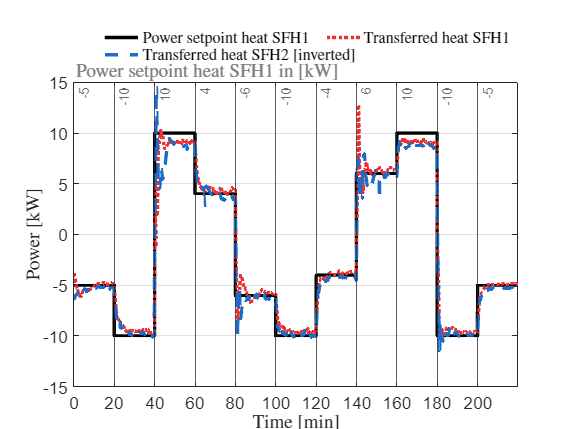


figure 


plot(value.Time_min_, value.SF1_fromLogic_CHN_CHN_P, value.Time_min_,  -value.SF1_Calc_CHN_P_TH,':', value.Time_min_,  value.SF2_Calc_CHN_P_TH,'--', 'LineWidth', LineWidth)
colors = [Color.Black1;Color.Red1;  Color.Blue1];
colororder(colors)
ylabel(yAxis.Q)
xlabel(xAxis.Timemin)
axis ([0 inf -15 15])
xticks(0:20:value.Time_min_(size(data,1)))
% xline(Changemin ,'-')
xline(Changemin, '-', xAxis.LabelSF1)

%set(gca, 'FontName', FontName);
set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gcf,'units','points','Position',[0,0,width,height])
set(get(gca,'title'),'Position',[0 15 1.1])

%title('Transfered Heat')
title('Power setpoint heat SFH1  in [kW]', 'Color', grey , 'FontSize', FS.Title)
legend( 'Power setpoint heat SFH1','Transferred heat SFH1',' Transferred heat SFH2 [inverted]','FontSize',FS.legend,'Location','northoutside','Orientation','horizontal','Interpreter','latex','NumColumns', 2);
legend('boxoff')

grid on 

set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gcf,'units','points','Position',[0,0,width,height])
set(get(gca,'title'),'Position',[0 15 1.1])

exportgraphics(gcf,'TransferdHeat.eps')

### Boundary Conditions: 

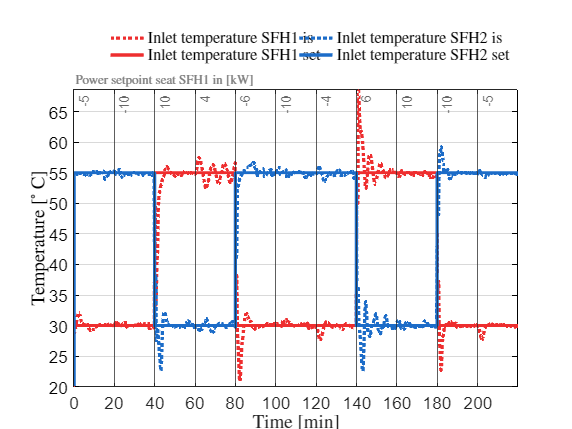

figure

plot(value.Time_min_, value.SF1_boundary_temp, 'Color', Color.Red1, 'LineStyle',':', 'LineWidth', LineWidth);
hold on;
plot(value.Time_min_, value.SF2_boundary_temp, 'Color', Color.Blue1, 'LineStyle',':', 'LineWidth', LineWidth);
plot(value.Time_min_, Inputs.SF1Mixer, 'Color', Color.Red1, 'LineWidth', LineWidth);
plot(value.Time_min_, Inputs.SF2Mixer, 'Color', Color.Blue1, 'LineWidth', LineWidth);

ylabel(yAxis.Temp)
ax = gca;
ax.YColor = 'black';
axis([0 inf 20 inf])
colors = [Color.Red1; Color.Blue1; Color.Red2; Color.Blue2; Color.Black1];
colororder(colors)

xticks(0:20:value.Time_min_(size(data,1)))
xline(Changemin, '-', xAxis.LabelSF1)
xlabel(xAxis.Timemin)




 set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gca, 'FontSize', FS.axis);
set(gcf,'units','points','Position',[0,0,width,height])
% set(get(gca,'title'),'Position',[0 68.5 1.1])


title('Power setpoint seat SFH1  in [kW]', 'Color', grey , 'FontSize', FS.Title)

legend('Inlet temperature SFH1 is', 'Inlet temperature SFH2 is', 'Inlet temperature SFH1 set', 'Inlet temperature SFH2 set' ,'FontSize',FS.legend, 'Location', 'northoutside', 'Orientation', 'horizontal', 'Interpreter', 'latex', 'NumColumns', 2);
legend('boxoff')
grid on 

exportgraphics(gcf,'BoundaryConditions.eps')

### low Prio Temp

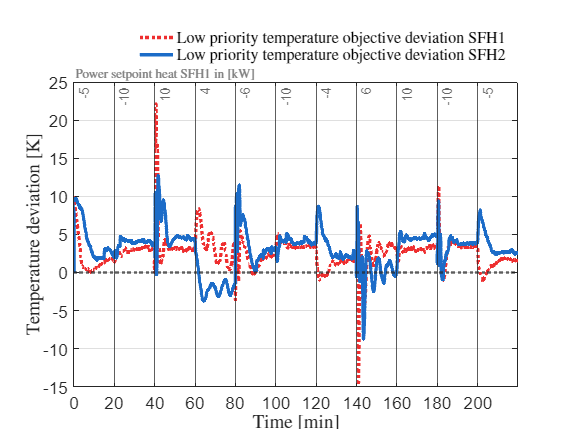

figure 


plot(value.Time_min_, Inputs.SF1diffTemp - value.SF1_dT ,':', value.Time_min_, Inputs.SF2diffTemp - value.SF2_dT , 'LineWidth', LineWidth)%, value.Time_min_, Inputs.SF1diffTemp, value.Time_min_, Inputs.SF1diffTemp)
colors = [Color.Red1; Color.Blue1; Color.Black1; Color.Black1];
colororder(colors)
ylabel(yAxis.dTemp)
xlabel(xAxis.Timemin)
axis ([0 inf -15 25])
xticks(0:20:value.Time_min_(size(data,1)))
xline(Changemin ,'-',xAxis.LabelSF1)
yline(0,'LineWidth',2,'LineStyle',':')


 set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gca, 'FontSize', FS.axis);
set(gcf,'units','points','Position',[0,0,width,height])
set(get(gca,'title'),'Position',[0 25 1.1])


%title('low prio Temperatures deviation ')
title('Power setpoint heat SFH1  in [kW]', 'Color', grey , 'FontSize', FS.Title)
%legend( 'temperature difference SF1 is','temperature difference SF2 is','temperature difference SF1 set','temperature difference SF2 set','Location','northoutside','Orientation','horizontal','Interpreter','latex', 'NumColumns',2 );
legend( 'Low priority temperature objective deviation SFH1','Low priority temperature objective deviation SFH2','Location','northoutside','FontSize',FS.legend,'Orientation','horizontal','Interpreter','latex', 'NumColumns',1 );
legend('boxoff')
grid on 
exportgraphics(gcf,'lowprioTemp.eps')

### high Prio Temp

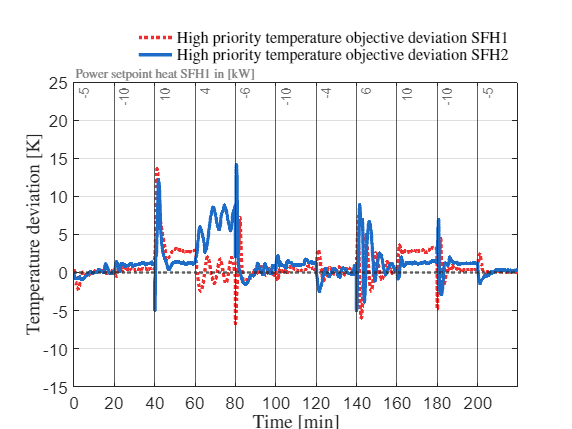

figure 


plot(value.Time_min_, Inputs.SF1Temp - value.SF1_T, ':', value.Time_min_, Inputs.SF2Temp - value.SF2_T, 'LineWidth', LineWidth)%, value.Time_min_, Inputs.SF1Temp, value.Time_min_, Inputs.SF2Temp )
colors = [Color.Red1; Color.Blue1;Color.Red2; Color.Blue2];
colororder(colors)
ylabel(yAxis.dTemp)
xlabel(xAxis.Timemin)
axis ([0 inf -15 25])
xticks(0:20:value.Time_min_(size(data,1)))
xline(Changemin ,'-',xAxis.LabelSF1)
yline(0,'LineWidth',2,'LineStyle',':')

 set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gca, 'FontSize', FS.axis);
set(gcf,'units','points','Position',[0,0,width,height])
set(get(gca,'title'),'Position',[0 25 1.1])


%title('high prio Temperatures deviation ')
title('Power setpoint heat SFH1  in [kW]', 'Color', grey , 'FontSize', FS.Title)
%legend( 'temperature SF1 is','temperature SF2 is','temperature SF1 set','temperature SF2 set','Location','northoutside','Orientation','horizontal','Interpreter','latex', 'NumColumns',2 );
legend( 'High priority temperature objective deviation SFH1','High priority temperature objective deviation SFH2','Location','northoutside','FontSize',FS.legend,'Orientation','horizontal','Interpreter','latex', 'NumColumns',1 );
legend('boxoff')
grid on 
exportgraphics(gcf,'highprioTemp.eps')

###  Errors and Actuators 

SF1

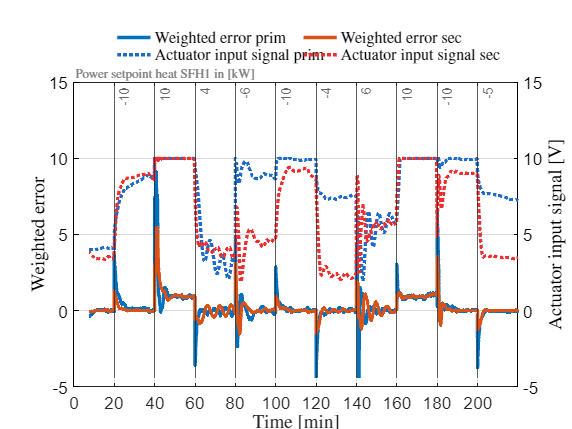

figure 


plot(value.Time_min_, value.SF1_e_prim,value.Time_min_,value.SF1_e_sec, 'LineWidth', LineWidth)
ylabel(yAxis.Error)
ax = gca;
ax.YColor = 'black';
axis ([0 inf -5 15])


yyaxis right 
plot(value.Time_min_, value.SF1_prim_active, ':' ,  value.Time_min_,value.SF1_sec_active, ':', 'LineWidth', LineWidth)
ylabel(yAxis.In)
axis ([0 inf -5 15])
ax = gca;
ax.YColor = 'black';


%title('Errors and Actuators SF1')

colors = [Color.Blue1; Color.Red1; Color.Blue1;Color.Red1];
colororder(colors)
xticks(0:20:value.Time_min_(size(data,1)))
xline(Changemin ,'-',xAxis.LabelSF1)


set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gca, 'FontSize', FS.axis);
set(gcf,'units','points','Position',[0,0,width,height])
set(get(gca,'title'),'Position',[0 15 1.1])


%title('high prio Temperatures deviation ')
title('Power setpoint heat SFH1  in [kW]', 'Color', grey , 'FontSize', 10)
legend( 'Weighted error prim','Weighted error sec','Actuator input signal prim','Actuator input signal sec','Location','northoutside','FontSize',FS.legend,'Orientation','horizontal','Interpreter','latex', 'NumColumns',2);
legend('boxoff')
xlabel(xAxis.Timemin)
grid on 
exportgraphics(gcf,'ErvsAcSF1.eps')

SF2

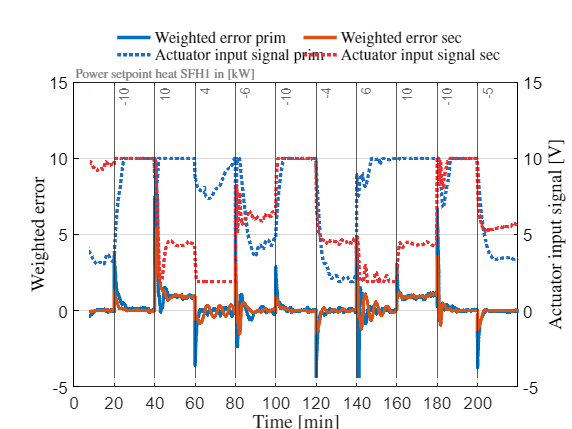

figure 


plot(value.Time_min_, value.SF2_e_prim,value.Time_min_,value.SF2_e_sec, 'LineWidth', LineWidth)
ylabel(yAxis.Error)
ax = gca;
ax.YColor = 'black';
axis ([0 inf -5 15])


yyaxis right 
plot(value.Time_min_, value.SF2_prim_active, ':' ,  value.Time_min_,value.SF2_sec_active,':', 'LineWidth', LineWidth)
ylabel(yAxis.In)
axis ([0 inf -5 15])
ax = gca;
ax.YColor = 'black';


%title('Errors and Actuators SF2')

colors = [Color.Blue1; Color.Red1; Color.Blue1;Color.Red1];
colororder(colors)
xticks(0:20:value.Time_min_(size(data,1)))
xline(Changemin ,'-',xAxis.LabelSF1)


set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment','left');
set(gca, 'FontSize', FS.axis);
set(gcf,'units','points','Position',[0,0,width,height])
set(get(gca,'title'),'Position',[0 15 1.1])

title('Power setpoint heat SFH1  in [kW]', 'Color', grey , 'FontSize', 10)
legend( 'Weighted error prim','Weighted error sec','Actuator input signal prim','Actuator input signal sec','Location','northoutside','FontSize',FS.legend,'Orientation','horizontal','Interpreter','latex', 'NumColumns',2);
legend('boxoff')
xlabel(xAxis.Timemin)
grid on 
exportgraphics(gcf,'ErvsAcSF2.eps')

Boundaryarray

boundary = [value.SF1_boundary_temp', value.SF2_boundary_temp'];
%writematrix(boundary, 'BoundaryTemperatures.csv');

% % Erstelle das Diagramm für SF2 mit zwei Achsen
% figure;
% 
% % Plot der ersten Linie auf der linken y-Achse
% yyaxis left;
% plot(value.Time_min_, value.SF2_e_prim, 'LineWidth', LineWidth);
% hold on;
% 
% % Plot der zweiten Linie auf der linken y-Achse
% plot(value.Time_min_, value.SF2_e_sec, 'LineWidth', LineWidth, 'LineStyle', '--');
% ylabel('Error');
% ax = gca;
% ax.YColor = 'black';
% axis([0 inf -5 15]);
% 
% % Plot der Linien auf der rechten y-Achse
% yyaxis right;
% plot(value.Time_min_, value.SF2_prim_active, ':', 'LineWidth', LineWidth);
% hold on;
% plot(value.Time_min_, value.SF2_sec_active, ':', 'LineWidth', LineWidth);
% ylabel('Input');
% ax = gca;
% ax.YColor = 'black';
% axis([0 inf -5 15]);
% 
% % Legende und Beschriftungen
% colors = [Color.Blue1; Color.Red1; Color.Blue1; Color.Red1];
% colororder(colors);
% xticks(0:20:value.Time_min_(end));
% xline(Changemin, '-', xAxis.LabelSF1);
% set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment', 'left');
% set(gca, 'FontSize', FS.axis);
% title('Power setpoint heat SFH1 in [kW]', 'Color', grey, 'FontSize', 10);
% legend('Weighted error prim', 'Weighted error sec', 'Actuator input signal prim', 'Actuator input signal sec', 'Location', 'northoutside', 'FontSize', FS.legend, 'Orientation', 'horizontal', 'Interpreter', 'latex', 'NumColumns', 2);
% legend('boxoff');
% xlabel('Time (min)');
% grid on;
% 
% % Anpassung der Figurengröße basierend auf der ersten Figur
% width = 800; % Breite der Figuren in Punkten
% height = 400; % Höhe der Figuren in Punkten
% set(gcf, 'Units', 'points', 'Position', [0, 0, width, height]);
% set(get(gca, 'title'), 'Position', [0 15 1.1]);
% 
% % Exportiere die Figur als Bild
% exportgraphics(gcf, 'ErvsAcSF2.eps', 'ContentType', 'vector');
% 
% 
% % Erstelle das Diagramm für die High-Priority-Temperaturabweichungen
% figure;
% 
% % Plot der Temperaturabweichungen
% plot(value.Time_min_, Inputs.SF1Temp - value.SF1_T, ':', value.Time_min_, Inputs.SF2Temp - value.SF2_T, 'LineWidth', LineWidth);
% ylabel('Temperature');
% xlabel('Time (min)');
% axis([0 inf -15 25]);
% xticks(0:20:value.Time_min_(end));
% xline(Changemin, '-', xAxis.LabelSF1);
% yline(0, 'LineWidth', 2, 'LineStyle', ':');
% set(gca, 'FontSize', FS.axis, 'TitleHorizontalAlignment', 'left');
% set(gca, 'FontSize', FS.axis);
% title('Power setpoint heat SFH1 in [kW]', 'Color', grey, 'FontSize', FS.Title);
% legend('High priority temperature deviation SFH1', 'High priority temperature deviation SFH2', 'Location', 'northoutside', 'FontSize', FS.legend, 'Orientation', 'horizontal', 'Interpreter', 'latex', 'NumColumns', 1);
% legend('boxoff');
% grid on;
% 
% % Anpassung der Figurengröße basierend auf der ersten Figur
% set(gcf, 'Units', 'points', 'Position', [0, 0, width, height]);
% set(get(gca, 'title'), 'Position', [0 25 1.1]);
% 
% % Exportiere die Figur als Bild
% exportgraphics(gcf, 'highprioTemp.eps', 'ContentType', 'vector');
